# Spike prediction

## Measure similarity between stimulus pattern and STA

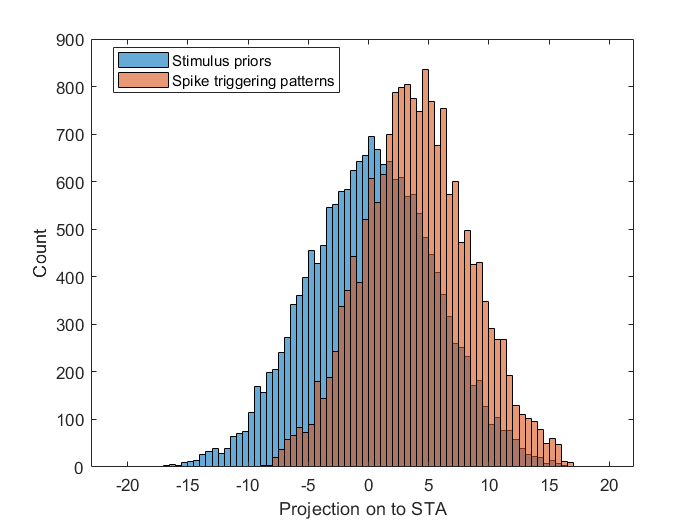

all_patterns = [all_spike_triggers; stimulus_prior];
% similarity_all = zeros([size(all_patterns,1) 1]);
% similarity_spike_triggers = zeros([size(all_spike_triggers,1) 1]);
% similarity_priors = zeros([size(stimulus_prior,1) 1]);

% for i = 1:size(all_patterns,1)
%     s_STA = corrcoef(STA, all_patterns(i,:));
%     similarity_all(i) = s_STA(2);
% end

similarity_all = dot(repmat(STA,length(all_patterns),1),all_patterns,2);
similarity_priors = dot(repmat(STA,length(stimulus_prior),1),stimulus_prior,2);
similarity_spike_triggers = dot(repmat(STA,length(all_spike_triggers),1),all_spike_triggers,2);

% histogram(similarity_all); hold on;
figure;
histogram(similarity_priors); hold on;
histogram(similarity_spike_triggers);
xlabel('Projection on to STA');
ylabel('Count');
legend('Stimulus priors', 'Spike triggering patterns', 'Location',"best");

## Calculate probabilities

spike_window = P.fs*1e-3;
eVec1Norm = eVec1_orth/max(eVec1);
eVec2Norm = eVec2_orth/max(eVec2);
eVec3Norm = eVec3_orth/max(eVec3);
% eVec4Norm = eVec4_orth/max(eVec4);

locs_ref = find(raster_data(1,:)==1);
ref = locs_ref(1);

stim_pattern = zeros(length(locs_ref),length(STA));
Pc_spike_stim = nan(1,length(locs_ref));
similarity_STA = nan(length(locs_ref),1);
similarity_EVec1 = nan(length(locs_ref),1);
similarity_EVec1_diff = nan(length(locs_ref),1);
similarity_EVec2 = nan(length(locs_ref),1);
similarity_EVec2_diff = nan(length(locs_ref),1);
similarity_EVec3 = nan(length(locs_ref),1);
similarity_EVec4 = nan(length(locs_ref),1);
similarity_STA_corrcoef = nan(length(locs_ref),1);
similarity_EVec1_corrcoef = nan(length(locs_ref),1);

Nspikes = length(locs_ref);
for j = 1:length(locs_ref)
    
%     if locs_ref(j) > ref+spike_window
        ref = locs_ref(j);
        
        if ref>stim_window*P.fs && (ref+spike_window)<length(stimulus)
            [spike_rows_trials, locs] = find(raster_data(:,ref-spike_window : ref+spike_window)==1);
            locs_trials = ref+locs-spike_window-1; % 11 to get the actual location from raster_data
            
            stim_pattern(j,:) = mean(stimulus(:,ref-stim_window*P.fs-1:ref-1),1);
            Nspikes(j) = length(locs);
            Pc_spike_stim(j) = length(locs)/nTrials;
            s_STA = corrcoef(STA, stim_pattern(j,:), "Rows","complete");
            similarity_STA_corrcoef(j) = s_STA(2);
            
            s_ev1 = corrcoef(eVec1Norm, stim_pattern(j,:), "Rows","complete");
            similarity_EVec1_corrcoef(j) = s_ev1(2);
            
            similarity_STA(j) = dot(STA,(stim_pattern(j,:))');%/dot(STA,stimulus_prior(1,:));
            similarity_EVec1(j) = dot(eVec1Norm, (stim_pattern(j,:))');
            similarity_EVec1_diff(j) = dot(diff(eVec1Norm), (stim_pattern(j,1:end-1))');
            similarity_EVec2(j) = dot(eVec2Norm, (stim_pattern(j,:))');
            similarity_EVec2_diff(j) = dot(diff(eVec2Norm), (stim_pattern(j,1:end-1))');
%             similarity_EVec3(j) = dot(eVec3Norm, (stim_pattern(j,:))');
%             similarity_EVec4(j) = dot(eVec4Norm, (stim_pattern(j,:))');
%             s_ev = corrcoef(eVec1, stim_pattern(j,:));
%             similarity_ev(j) = s_ev(2);
            
        end
        
end


## Using dot product for similarity

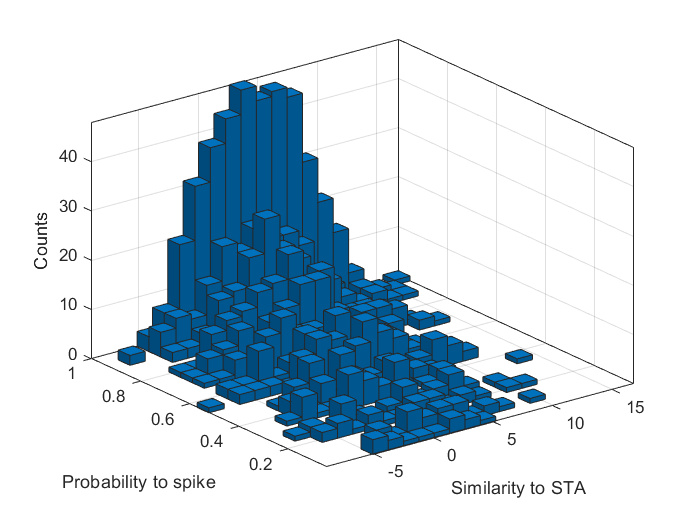


% T = table(stim_pattern, Pc_spike_stim, similarity_STA, similarity_ev);
figure;
histogram2(similarity_STA,Pc_spike_stim',20);
xlabel('Similarity to STA');
ylabel('Probability to spike');
zlabel('Counts');

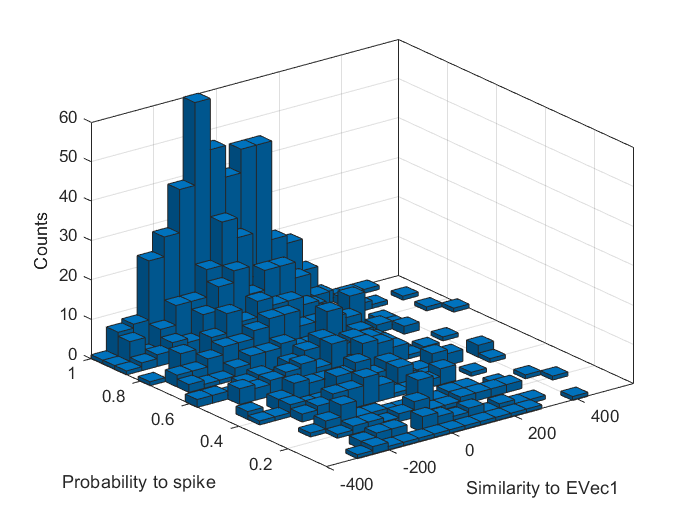


% figure;
% f = fit([similarity_STA,similarity_EVec2],Pc_spike_stim','poly11' , 'Exclude', isnan(Pc_spike_stim) )
% plot(f,similarity_STA,Pc_spike_stim);
% histogram2(similarity_ev,Pc_spike_stim);

figure;
histogram2(similarity_EVec1,Pc_spike_stim',20);
xlabel('Similarity to EVec1');
ylabel('Probability to spike');
zlabel('Counts');

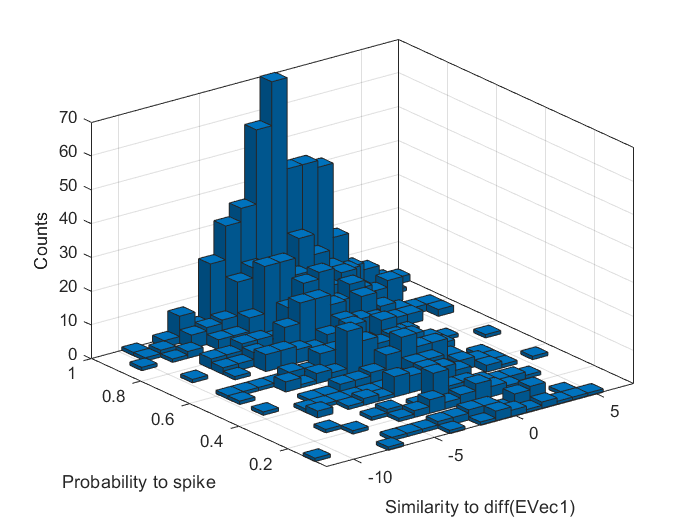


figure;
histogram2(similarity_EVec1_diff,Pc_spike_stim',20);
xlabel('Similarity to diff(EVec1)');
ylabel('Probability to spike');
zlabel('Counts');

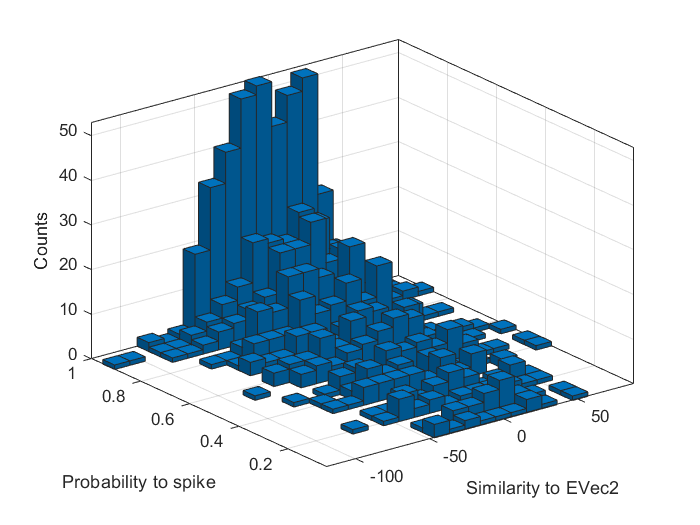


% figure;
% scatter(similarity_EVec1,Pc_spike_stim);

figure;
histogram2(similarity_EVec2,Pc_spike_stim',20);
xlabel('Similarity to EVec2');
ylabel('Probability to spike');
zlabel('Counts');

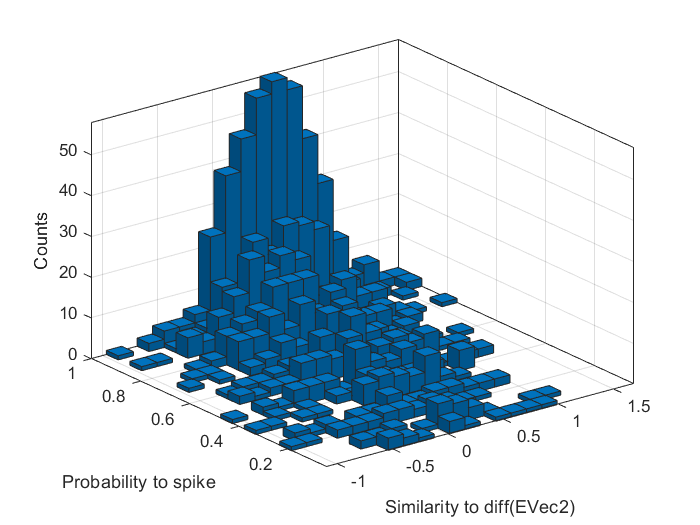


figure;
histogram2(similarity_EVec2_diff,Pc_spike_stim',20);
xlabel('Similarity to diff(EVec2)');
ylabel('Probability to spike');
zlabel('Counts');


% figure;
% histogram2(similarity_EVec3,Pc_spike_stim',20);
% xlabel('Similarity to EVec3');
% ylabel('Probability to spike');
% 
% figure;
% histogram2(similarity_EVec4,Pc_spike_stim',20);
% xlabel('Similarity to EVec4');
% ylabel('Probability to spike');
% figure;
% mesh(similarity_EVec1,similarity_EVec2, Pc_spike_stim);

% [similarity_sorted,idx] = sort(similarity_STA);
% Pc_spike_stim_sorted = Pc_spike_stim(idx);

% plot(similarity_STA,Pc_spike_stim, 'o');

% figure; histogram(similarity_STA);

## Using correlation coefficient

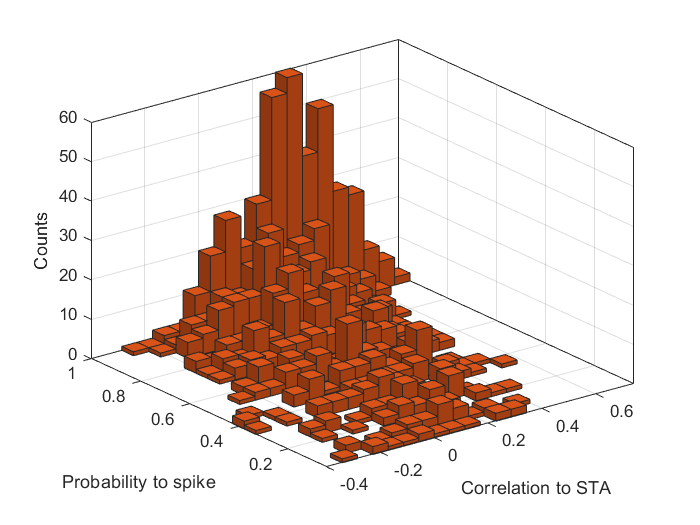


% figure; histogram(similarity_STA_corrcoef);
% title('Similarity histogram with corrcoef measure')
% figure; plot(similarity_STA_corrcoef,Pc_spike_stim, 'o');

figure; histogram2(similarity_STA_corrcoef,Pc_spike_stim',20, 'DisplayStyle','bar3', "FaceColor",[0.8500 0.3250 0.0980]);
xlabel('Correlation to STA');
ylabel('Probability to spike');
zlabel('Counts');


ind = isnan(similarity_EVec1_corrcoef);
similarity_STA_corrcoef(ind)=[];
similarity_EVec1_corrcoef(ind) = [];
Pc_spike_stim(ind) = [];

% figure;
% % plot(similarity_ev, Pc_spike_stim, '.');
% f = fit([similarity_STA_corrcoef similarity_EVec1_corrcoef], Pc_spike_stim','poly11');
% plot(f,[similarity_STA_corrcoef similarity_EVec1_corrcoef], Pc_spike_stim');


